# Projekt 1

#### Przykład - wyświetlenie wczytanego obrazu oraz informacji o oknie

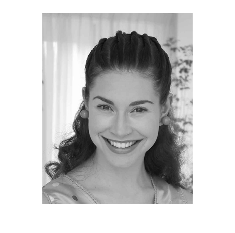

info = imfinfo('data/portret.jpg');
L1=imread('data/portret.jpg');
figure(1);
imshow(L1);

get(1);

                 Alphamap: [0 0.0159 0.0317 0.0476 0.0635 0.0794 0.0952 0.1111 0.1270 0.1429 0.1587 … ]
             BeingDeleted: off
               BusyAction: 'queue'
            ButtonDownFcn: ''
                 Children: [1×1 Axes]
                 Clipping: on
          CloseRequestFcn: 'closereq'
                    Color: [1 1 1]
                 Colormap: [256×3 double]
              ContextMenu: [0×0 GraphicsPlaceholder]
                CreateFcn: ''
              CurrentAxes: [1×1 Axes]
         CurrentCharacter: ''
            CurrentObject: [0×0 GraphicsPlaceholder]
             CurrentPoint: [0 0]
                DeleteFcn: ''
             DockControls: on
                 FileName: ''
        GraphicsSmoothing: on
         HandleVisibility: 'on'
                     Icon: ''
            InnerPosition: [727 537 466 463]
            IntegerHandle: on
            Interruptible: on
           InvertHardcopy: on
              KeyPressFcn: ''
            KeyReleaseFcn: ''
   

*imfinfo zwraca wartość typu struct, do poszczególnych elementów można się odwołać po nazwie np. info.FileSize*

*imshow(L, [low high]) – wyświetla macierz jako obraz z określonymi poziomami na wyjściu, wszystko poniżej low jest czarne, powyżej high jest białe*

*figure(h) – tworzy nowe okno z uchwytem h*

*get(h) – wyświetla właściwości obiektu o uchwycie h*

*set(h) – pozwala ustawić wartość danej właściwości*

*gcf – (get current figure) zwraca wartość uchwytu aktualnie używanego okna graficznego*

### Zadanie 1

Dokonaj przesunięcia obrazu w układzie kartezjańskim, przyjmując kierunek przesunięcia do góry i w prawo. Wykonaj zadanie na dwa sposoby - z zachowaniem oryginalnej powierzchni obrazu oraz z rozszerzeniem jej.

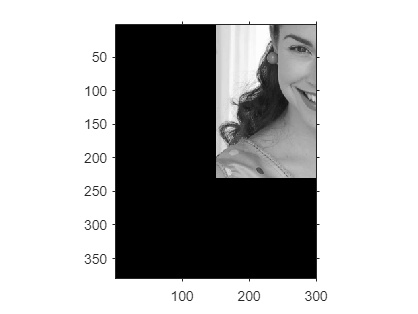

L1_translated_1 = imtranslate(L1,[150, -150]);
imshow(L1_translated_1);

set(gca,'Visible','on');

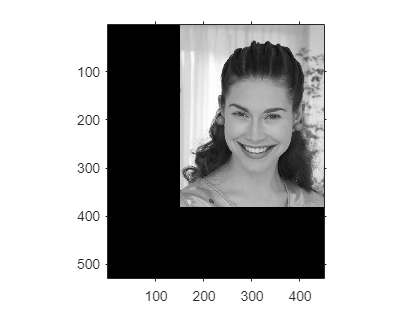


%----------------


L1_translated_2 = imtranslate(L1,[150, -150],'OutputView','full');
imshow(L1_translated_2);

set(gca,'Visible','on');

### Zadanie 2

Dokonaj obrotu obrazu w układzie kartezjańskim o dowolny kąt. Wykonaj zadanie na dwa sposoby - z zachowaniem oryginalnej powierzchni obrazu oraz z rozszerzeniem jej.

L1_rotated_1 = imrotate(L1,45,'crop')

L1_rotated_1 = 380×300 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

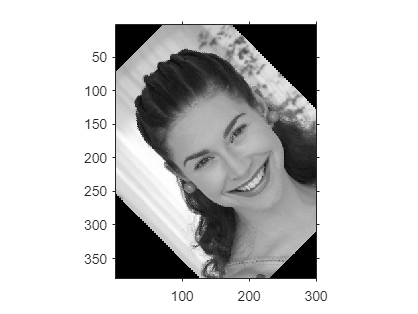

imshow(L1_rotated_1);

set(gca,'Visible','on');


%----------------

L1_rotated_2 = imrotate(L1,45)

L1_rotated_2 = 481×481 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

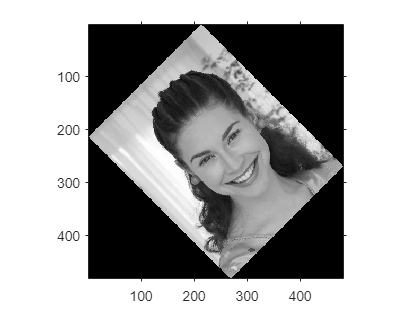

imshow(L1_rotated_2);

set(gca,'Visible','on');

### Zadanie 3

Wykonaj przekształcenia obrazu - odbicie względem osi poziomej oraz pionowej, następnie połącz obrazy, aby tworzyły następujący układ:

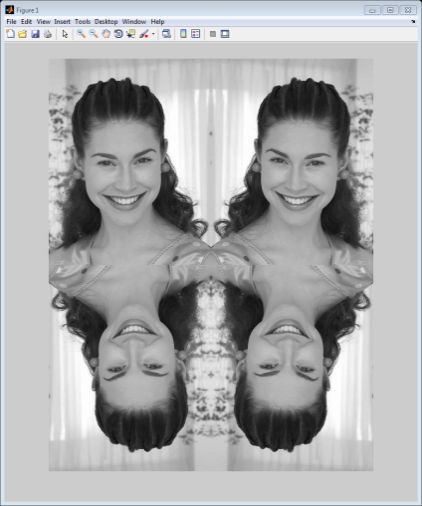

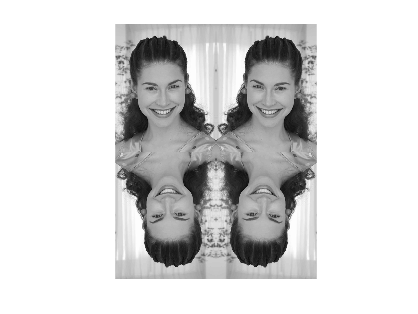

I1 = flip(L1 ,2);
I2 = flipud(L1);
I3 = flip(I2 ,2);

upper = cat(2,I1,L1);
lower = cat(2,I2,I3);

final = cat(1, upper, lower);
imshow(final);

#### Przydatne funkcje

*imtranslate*

*imrotate*

*fliplr*

*flipud*